# Practica 3. Convolucion de Tiempo Discreto

1. Utilice la funciónconv()de MATLAB para calcularla convoluciónde las siguientes secuencias:


$$x(n) =\left(\frac{4}{5}\right)

^n \left[ u(n)-u(n-5)\right] $$
      
$$h(n) =\left(\frac{2}{3}\right)^n \left[ u(n)-u(n-5)\right] $$


a) Grafique x(n)  y h(n)

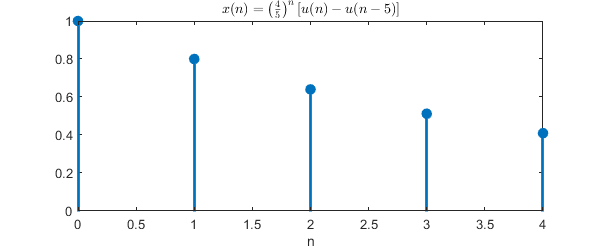

escalon = @(n) n>=0;
n = 0:4;
figure('Position',[500 400 600 250])
x = ((4/5).^n).*( escalon(n)-escalon(n-5) );
stem(n,x,'filled','LineWidth',2)
title('$ x(n) =\left(\frac{4}{5}\right)^n \left[ u(n)-u(n-5)\right]  $','Interpreter','latex')
xlabel('n')

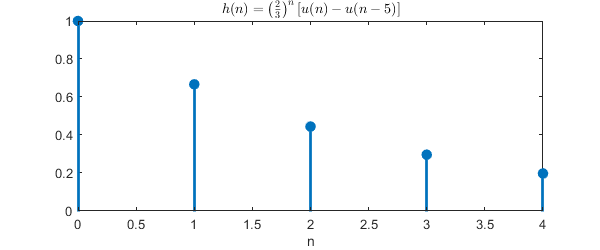

n = 0:4;
figure('Position',[500 400 600 250])
h = ((2/3).^n).*( escalon(n)-escalon(n-5) );
stem(n,h,'filled','LineWidth',2)
title('$ h(n) =\left(\frac{2}{3}\right)^n \left[ u(n)-u(n-5)\right] $','Interpreter','latex')
xlabel('n')

b) Grafique $y\left(n\right)=x\left(n\right)*h\left(n\right)$

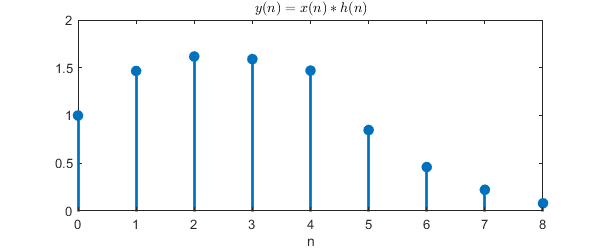

figure('Position',[500 400 600 250])
y = conv(x,h);
n = 0:8;
stem(n,y,'filled','LineWidth',2)
title('$ y(n) = x(n)*h(n) $','Interpreter','latex')
xlabel('n')

2. Utilice   la   función convmtx()de   MATLAB para determinarla matriz   de   convolucióncorrespondiente  a ℎ(𝑛)y  utilice la  matriz  obtenida para calcular la  convoluciónde  las siguientes secuencias:


$$x(n) =\left(\frac{1}{2}\right)

^n\left[ u(n)-u(n-4)\right] $$
      
$$h(n) =\left(\frac{1}{3}\right)^2 \left[ u(n)-u(n-4)\right] $$


a)  Obtenga la matriz H

n = 0:3;
figure('Position',[500 400 600 250])
h = ((1/3).^n).*( escalon(n)-escalon(n-4) );
h = convmtx(h,4).';
H = sym(h)

$$H = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ \frac{1}{3} & 1 & 0 & 0\\ \frac{1}{9} & \frac{1}{3} & 1 & 0\\ \frac{1}{27} & \frac{1}{9} & \frac{1}{3} & 1\\ 0 & \frac{1}{27} & \frac{1}{9} & \frac{1}{3}\\ 0 & 0 & \frac{1}{27} & \frac{1}{9}\\ 0 & 0 & 0 & \frac{1}{27} \end{array}\right)$$

b) Grafique $y\left(n\right)=x\left(n\right)*h\left(n\right)$

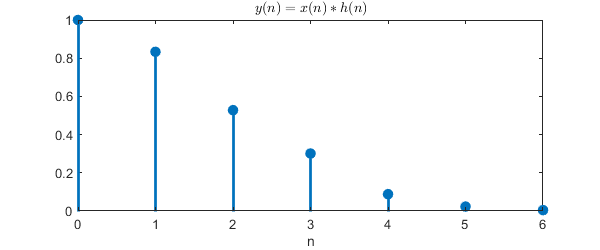

n = 0:3;
x = ((1/2).^n).*( escalon(n)-escalon(n-4) );
y = x.*h;
y = sum(y,2);
n = 0:6;
stem(n,y,'filled','LineWidth',2)
title('$ y(n) = x(n)*h(n) $','Interpreter','latex')
xlabel('n')

3. Utilice   la   funcióntoeplitz() de   MATLAB para determinar   la   matriz   de   convolucióncorrespondiente  a 𝑥(𝑛) y utilice la  matriz  obtenida para calcularla  convoluciónde  las siguientes secuencias:


$$x(n) =\left(\frac{1}{2}\right)

^n\left[ u(n)-u(n-4)\right] $$
      
$$h(n) =\left(\frac{1}{3}\right)^2 \left[ u(n)-u(n-4)\right] $$


a)  Obtenga la matriz X

n = 0:3;
figure('Position',[500 400 600 250])
x = ((1/2).^n).*( escalon(n)-escalon(n-4) );
x = convmtx(x,4).';
X = sym(x)

$$X = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ \frac{1}{2} & 1 & 0 & 0\\ \frac{1}{4} & \frac{1}{2} & 1 & 0\\ \frac{1}{8} & \frac{1}{4} & \frac{1}{2} & 1\\ 0 & \frac{1}{8} & \frac{1}{4} & \frac{1}{2}\\ 0 & 0 & \frac{1}{8} & \frac{1}{4}\\ 0 & 0 & 0 & \frac{1}{8} \end{array}\right)$$

    b) Grafique $y\left(n\right)=x\left(n\right)*h\left(n\right)$

n = 0:3;
h = ((1/3).^n).*( escalon(n)-escalon(n-4) );
y = x.*h;
y = sum(y,2);
n = 0:6;
stem(n,y,'filled','LineWidth',2)
title('$ y(n) = x(n)*h(n) $','Interpreter','latex')
xlabel('n')